## Given parameters

clc; clear all; close all;



syms phi theta phi_dot theta_dot phi_ddot theta_ddot phi_ref theta_ref theta0 phi0
syms t tau
syms l_p l_w m_w m_p g k_phi k_theta d_theta d_phi x x_ddot x_dot J_p J_w d_thetadot d_phidot 
q = [theta ; phi] , qdot =[theta_dot; phi_dot] , qddot = [theta_ddot; phi_ddot], q0 = [theta0;phi0]

$$q = \left(\begin{array}{c} \theta \\ \varphi \end{array}\right)$$

$$qdot = \left(\begin{array}{c} \dot{\theta }\\ \dot{\varphi } \end{array}\right)$$

$$qddot = \left(\begin{array}{c} \ddot{\theta }\\ \ddot{\varphi } \end{array}\right)$$

$$q0 = \left(\begin{array}{c} \theta_{0}\\ \varphi_{0} \end{array}\right)$$

w_angle = [0;0;theta+phi], p_angle = [0;0;theta]

$$w\_angle = \left(\begin{array}{c} 0\\ 0\\ \varphi +\theta \end{array}\right)$$

$$p\_angle = \left(\begin{array}{c} 0\\ 0\\ \theta \end{array}\right)$$

r1 = [x;0;0], r2 = [x + l_w*cos(theta); l_w*sin(theta);0], r3 = [x - l_p*cos(theta); l_p*sin(theta);0];

$$r1 = \left(\begin{array}{c} x\\ 0\\ 0 \end{array}\right)$$

$$r2 = \left(\begin{array}{c} x+l_{w}\,\cos\left(\theta \right)\\ l_{w}\,\sin\left(\theta \right)\\ 0 \end{array}\right)$$

r1_dot = [x_dot;0;0] , r2_dot = jacobian(r2,q)*qdot+r1_dot, r3_dot = jacobian(r3,q)*qdot+r1_dot;

$$r1\_dot = \left(\begin{array}{c} \dot{x}\\ 0\\ 0 \end{array}\right)$$

$$r2\_dot = \left(\begin{array}{c} \dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\\ l_{w}\,\dot{\theta }\,\cos\left(\theta \right)\\ 0 \end{array}\right)$$

T = J_w * (theta_dot + phi_dot)^2 / 2 + J_p * theta_dot^2 / 2 +  m_p * ((x_dot- theta_dot * l_p * sin(theta))^2 + (theta_dot^2 * l_p^2 * cos(theta)^2)) /2 + m_w * ((x_dot - theta_dot * l_w * sin(theta))^2 + (theta_dot^2 * l_w^2 *cos(theta)^2))/2

$$T = \frac{J_{w}\,{\left(\dot{\varphi }+\dot{\theta }\right)}^{2}}{2}+\frac{J_{p}\,{\dot{\theta }}^{2}}{2}+\frac{m_{p}\,\left({\left(\dot{x}-l_{p}\,\dot{\theta }\,\sin\left(\theta \right)\right)}^{2}+{l_{p}}^{2}\,{\dot{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}\right)}{2}+\frac{m_{w}\,\left({\left(\dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\right)}^{2}+{l_{w}}^{2}\,{\dot{\theta }}^{2}\,{\cos\left(\theta \right)}^{2}\right)}{2}$$

M2 = [0;0;tau - d_phi*phi_dot], M3 = [0;0;d_phi*phi_dot-tau - d_theta*theta_dot]

$$M2 = \left(\begin{array}{c} 0\\ 0\\ \tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

$$M3 = \left(\begin{array}{c} 0\\ 0\\ d_{\varphi }\,\dot{\varphi }-\tau -d_{\theta }\,\dot{\theta } \end{array}\right)$$

jacobian(w_angle,q)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

jacobian(p_angle,q)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

Q2 = jacobian(w_angle,q).'*M2, Q3 = jacobian(p_angle,q).'*M3

$$Q2 = \left(\begin{array}{c} \tau -d_{\varphi }\,\dot{\varphi }\\ \tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

$$Q3 = \left(\begin{array}{c} d_{\varphi }\,\dot{\varphi }-\tau -d_{\theta }\,\dot{\theta }\\ 0 \end{array}\right)$$


Q = simplify(Q2+Q3)

$$Q = \left(\begin{array}{c} -d_{\theta }\,\dot{\theta }\\ \tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

## Question a)

Numerically calculate all equilibrium positions in the domain 0 ≤ θ ≤ π , −π ≤ ϕ ≤ π for the input τ = 0 and the prescribed displacement spd(t) = s˙pd(t) = s¨pd(t) = 0.

Uk = 1/2*k_theta*(theta-theta_ref)^2 + 1/2*k_phi*(phi-phi_ref)^2

$$Uk = \frac{k_{\varphi }\,{\left(\varphi -\varphi_{\mathrm{ref}}\right)}^{2}}{2}+\frac{k_{\theta }\,{\left(\theta -\theta_{\mathrm{ref}}\right)}^{2}}{2}$$

Vg = m_p * g * l_p * sin(theta) + m_w * g * l_w * sin(theta)

$$Vg = g\,l_{p}\,m_{p}\,\sin\left(\theta \right)+g\,l_{w}\,m_{w}\,\sin\left(\theta \right)$$

V = Uk + Vg

$$V = \frac{k_{\varphi }\,{\left(\varphi -\varphi_{\mathrm{ref}}\right)}^{2}}{2}+\frac{k_{\theta }\,{\left(\theta -\theta_{\mathrm{ref}}\right)}^{2}}{2}+g\,l_{p}\,m_{p}\,\sin\left(\theta \right)+g\,l_{w}\,m_{w}\,\sin\left(\theta \right)$$

V_transpose_partialderivative = jacobian(V,q).'

$$V\_transpose\_partialderivative = \left(\begin{array}{c} \frac{k_{\theta }\,\left(2\,\theta -2\,\theta_{\mathrm{ref}}\right)}{2}+g\,l_{p}\,m_{p}\,\cos\left(\theta \right)+g\,l_{w}\,m_{w}\,\cos\left(\theta \right)\\ \frac{k_{\varphi }\,\left(2\,\varphi -2\,\varphi_{\mathrm{ref}}\right)}{2} \end{array}\right)$$


subs_values = struct( ...
    'k_theta', 6.558, ...
    'k_phi', 0.114, ...
    'theta_ref', pi / 2, ...
    'phi_ref', 0.0, ...
    'g', 9.81, ...
    'm_p', 1.0, ...
    'l_p', 0.5, ...
    'm_w', 0.2, ...
    'l_w', 1 ...
);

% Substitute the numerical values into V and its gradient
V_numeric = subs(V_transpose_partialderivative, subs_values);



%Equilibrium conditions: k_theta*(theta-theta_ref) + cos(theta)* g *(m_p  * l_p + m_w * l_w ) = 0
                        % and k_phi*(phi-phi_ref) = 0;
%Formulas for equilibrium
phi_equilibrium = phi_ref;
theta_equilibrium = @(theta) k_theta * (theta - theta_ref) + cos(theta) * g * (m_p * l_p + m_w * l_w);
solutions = [];
for guess = -2*pi:0.1:2*pi
    critical_points = vpasolve(V_numeric == 0, q,guess);
    theta_sol = double(critical_points.theta);
    if ~ismember(theta_sol, solutions)
        solutions = [solutions, double(critical_points.theta)];
    end
end    
solutions.'

ans =     1.0476
    2.0940
    1.5708


## Question b)

For each equilibrium position, determine whether or not it is stable.

% To check for stability: det(K_0)>0
K0 = jacobian(V_transpose_partialderivative, q) 

$$K0 = \left(\begin{array}{cc} k_{\theta }-g\,l_{p}\,m_{p}\,\sin\left(\theta \right)-g\,l_{w}\,m_{w}\,\sin\left(\theta \right) & 0\\ 0 & k_{\varphi } \end{array}\right)$$

K = jacobian(V_numeric, q)

$$K = \left(\begin{array}{cc} \frac{3279}{500}-\frac{6867\,\sin\left(\theta \right)}{1000} & 0\\ 0 & \frac{57}{500} \end{array}\right)$$

for element = solutions
    K_0 = vpa(subs(K,'theta',element))
    if det(K_0) > 0
        disp("The equilibrium position is stable"); 
    else
        disp("The equilibrium position is NOT stable");
    end
end

$$K\_0 = \left(\begin{array}{cc} 0.60953694975053103444350827304431 & 0\\ 0 & 0.114 \end{array}\right)$$

The equilibrium position is stable


$$K\_0 = \left(\begin{array}{cc} 0.60953694975053061427227178709904 & 0\\ 0 & 0.114 \end{array}\right)$$

The equilibrium position is stable


$$K\_0 = \left(\begin{array}{cc} -0.309 & 0\\ 0 & 0.114 \end{array}\right)$$

The equilibrium position is NOT stable


## Question c)

Linearize the equations of motion—that are computed in question e of deliverable 1— around a stable equilibrium position (also use the prescribed displacement as defined in Question 2a). For the set of linear equations, add the symbolic expressions for M, D, K, K Q and Q to the answerform_2.docx document. 

Note that: If you found multiple stable equilibria in questions a and b, please consider the equilibrium ”closest (i.e., magnitude of difference) to” q = [0,0] .

T_qdot = jacobian(T,qdot).'

$$T\_qdot = \begin{array}{l} \left(\begin{array}{c} J_{p}\,\dot{\theta }+\sigma_{1}-\frac{m_{p}\,\left(2\,l_{p}\,\sin\left(\theta \right)\,\left(\dot{x}-l_{p}\,\dot{\theta }\,\sin\left(\theta \right)\right)-2\,{l_{p}}^{2}\,\dot{\theta }\,{\cos\left(\theta \right)}^{2}\right)}{2}-\frac{m_{w}\,\left(2\,l_{w}\,\sin\left(\theta \right)\,\left(\dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\right)-2\,{l_{w}}^{2}\,\dot{\theta }\,{\cos\left(\theta \right)}^{2}\right)}{2}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{J_{w}\,\left(2\,\dot{\varphi }+2\,\dot{\theta }\right)}{2} \end{array}$$

T_q = jacobian(T,q).'

$$T\_q = \left(\begin{array}{c} -\frac{m_{p}\,\left(2\,l_{p}\,\dot{\theta }\,\cos\left(\theta \right)\,\left(\dot{x}-l_{p}\,\dot{\theta }\,\sin\left(\theta \right)\right)+2\,{l_{p}}^{2}\,{\dot{\theta }}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\right)}{2}-\frac{m_{w}\,\left(2\,l_{w}\,\dot{\theta }\,\cos\left(\theta \right)\,\left(\dot{x}-l_{w}\,\dot{\theta }\,\sin\left(\theta \right)\right)+2\,{l_{w}}^{2}\,{\dot{\theta }}^{2}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\right)}{2}\\ 0 \end{array}\right)$$


M0 = simplify(jacobian(T_qdot,qdot));
D0 = -jacobian(Q,qdot);
K0Q = jacobian(Q,q);

M0 = subs(M0,q,q0)

$$M0 = \left(\begin{array}{cc} m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p}+J_{w} & J_{w}\\ J_{w} & J_{w} \end{array}\right)$$

K0 = subs(K0,q,q0)

$$K0 = \left(\begin{array}{cc} k_{\theta }-g\,l_{p}\,m_{p}\,\sin\left(\theta_{0}\right)-g\,l_{w}\,m_{w}\,\sin\left(\theta_{0}\right) & 0\\ 0 & k_{\varphi } \end{array}\right)$$

K0Q = subs(K0Q,[q,qdot],[q0,[0;0]])

$$K0Q = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$

D0 = subs(D0,[q,qdot],[q0,[0;0]])

$$D0 = \left(\begin{array}{cc} d_{\theta } & 0\\ 0 & d_{\varphi } \end{array}\right)$$


LinEOM = M0*qddot + D0*qdot + (K0 + K0Q)*q == Q

$$LinEOM = \left(\begin{array}{c} J_{w}\,\ddot{\varphi }-\theta \,\left(g\,l_{p}\,m_{p}\,\sin\left(\theta_{0}\right)-k_{\theta }+g\,l_{w}\,m_{w}\,\sin\left(\theta_{0}\right)\right)+d_{\theta }\,\dot{\theta }+\ddot{\theta }\,\left(m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p}+J_{w}\right)=-d_{\theta }\,\dot{\theta }\\ J_{w}\,\ddot{\varphi }+J_{w}\,\ddot{\theta }+d_{\varphi }\,\dot{\varphi }+k_{\varphi }\,\varphi =\tau -d_{\varphi }\,\dot{\varphi } \end{array}\right)$$

## Question d)

Generate a time trajectory with the linear equations as obtained from question c. In addition, simulate a time trajectory for the nonlinear system. Please consider the initial position and velocity q(0) = 1.1 1.7 ⊤ and ˙q(0) = 0 0⊤ in combination with τ(t) = 0, spd(t) = 0, and a simulation time of 82 seconds.

subs_values = struct( ...
    'k_theta', 6.558, ...
    'k_phi', 0.114, ...
    'theta_ref', pi / 2, ...
    'phi_ref', 0.0, ...
    'g', 9.81, ...
    'm_p', 1.0, ...
    'l_p', 0.5, ...
    'm_w', 0.2, ...
    'l_w', 1, ...
    'J_w', 0.1, ...
    'J_p', 0.083, ...
    'd_theta', 0.1, ...
    'd_phi', 0.2, ...
    'theta0', 1.0476 ...
);
A = [zeros(2), eye(2)
     -inv(M0)*(K0 + K0Q), -inv(M0)*D0]

$$A = \begin{array}{l} \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ \sigma_{3} & \frac{k_{\varphi }}{\sigma_{4}} & -\frac{d_{\theta }}{\sigma_{4}} & \frac{d_{\varphi }}{\sigma_{4}}\\ -\sigma_{3} & -\frac{k_{\varphi }\,\sigma_{2}}{\sigma_{1}} & \frac{d_{\theta }}{\sigma_{4}} & -\frac{d_{\varphi }\,\sigma_{2}}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=J_{w}\,m_{p}\,{l_{p}}^{2}+J_{w}\,m_{w}\,{l_{w}}^{2}+J_{p}\,J_{w}\\ \sigma_{2}=m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p}+J_{w}\\ \sigma_{3}=\frac{g\,l_{p}\,m_{p}\,\sin\left(\theta_{0}\right)-k_{\theta }+g\,l_{w}\,m_{w}\,\sin\left(\theta_{0}\right)}{\sigma_{4}}\\ \sigma_{4}=m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p} \end{array}$$

M0_inv = inv(M0)

$$M0\_inv = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1} & -\sigma_{1}\\ -\sigma_{1} & \frac{m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p}+J_{w}}{J_{w}\,m_{p}\,{l_{p}}^{2}+J_{w}\,m_{w}\,{l_{w}}^{2}+J_{p}\,J_{w}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p}} \end{array}$$


B = [zeros(2,1)
     inv(M0)*[0;1]]

$$B = \left(\begin{array}{c} 0\\ 0\\ -\frac{1}{m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p}}\\ \frac{m_{p}\,{l_{p}}^{2}+m_{w}\,{l_{w}}^{2}+J_{p}+J_{w}}{J_{w}\,m_{p}\,{l_{p}}^{2}+J_{w}\,m_{w}\,{l_{w}}^{2}+J_{p}\,J_{w}} \end{array}\right)$$

A = double(vpa(subs(A,subs_values)))

A =          0         0    1.0000         0
         0         0         0    1.0000
   -1.1438    0.2139   -0.1876    0.3752
    1.1438   -1.3539    0.1876   -2.3752


B = double(vpa(subs(B,subs_values)))

B =          0
         0
   -1.8762
   11.8762


% Define simulation time
tspan = [0 82];
class(A)

ans = 'double'

class(B)

ans = 'double'

% Initial conditions
q0 = [1.1; 1.7; 0; 0]; % [theta; phi; theta_dot; phi_dot]

% Define zero input torque
tau = 0;

% Define the linear system as a state-space system
sys_linear = @(t, x) A * x + B * tau

sys_linear = function_handle with value:
    @(t,x)A*x+B*tau


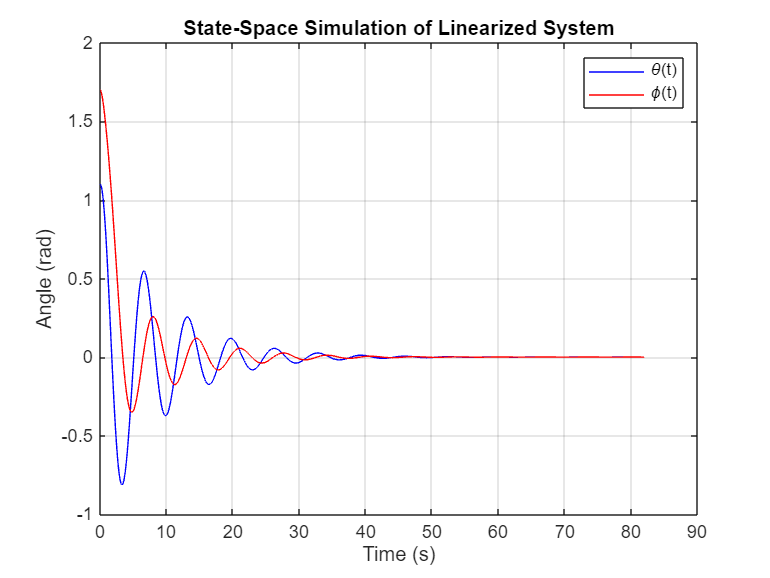


% Simulate using ode45
[t_linear, x_linear] = ode45(sys_linear, tspan, q0);




% Plot the results
figure;
plot(t_linear, x_linear(:,1), 'b-', 'DisplayName', '\theta(t)');
hold on;
plot(t_linear, x_linear(:,2), 'r-', 'DisplayName', '\phi(t)');
xlabel('Time (s)');
ylabel('Angle (rad)');
title('State-Space Simulation of Linearized System');
legend;
grid on;

## Question e)

Describe how each response of the linearized system compares to the response of the nonlinear system. What conclusions can be drawn from this?